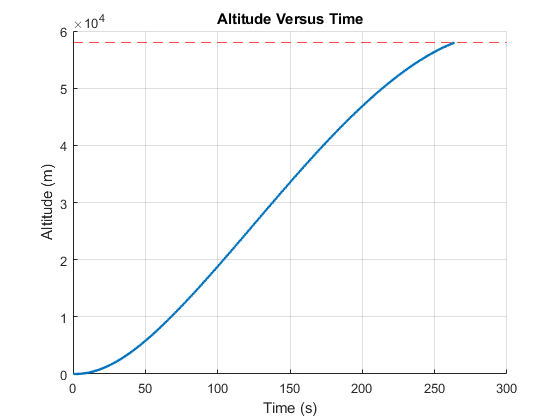

% AE414_Group10_Project_SP23
clear

g_mars_surf = 3.721; % gravitational acceleration at the surface of Mars (m/s^2)
g_e = 9.81;          % gravitational acceleration on Earth (m/s^2)
R_mars = 3389.5e3;   %m

tau = 170000;   % thrust of the rocket (N)
I_sp = 350;     % specific impuls of the rocket (s)

M_0 = 18000;    % inital mass of rocket (kg)
M_b = 5000;     % burnout mass of rocket (kg)
k = 18.6;       % initial kick angle (deg)

m_dot = tau/(g_e*I_sp); % mass flow rate calculation (kg/s)
u_eq = I_sp*g_e;        % equivalent exhaust velocity calculation (m/s)

A_f = pi*2.5^2/sin(pi/6);   % frontal area calculation (m^2)

u(1) = 0; % defining inital velocity
h(1) = 0; % defining inital altitude
x(1) = 0; % defining inital horizontal position

% Iterations

for t = 1:(M_0 - M_b)/m_dot % defining time iterations
    
    M(t) = M_0 - m_dot*t; % current mass calculation (kg)
    
    g(t) = g_mars_surf*(R_mars/(R_mars + h(t)))^2; % current gravitational acceleration calculation (m/s^2)
    
    if t < 10
        theta(t) = 0; % at t < 10, angle = 0 (rad)
    else
        theta(10) = k*pi/180; % at t = 10, angle = kick angle (rad)
        delta_theta(t) = g(t)*sin(theta(t))/u(t); % change in angle calculation (rad/s)
        theta(t+1) = theta(t) + delta_theta(t); % next angle calculation (rad)
    end
         
    P(t) = 0.699*exp(-9*10^(-5)*h(t)); % current pressure calculation (kPa)

    if h(t)<7000
        T(t) = -31 - 9.98*10^(-4)*h(t); % current temperature calculation if altitude is under 7000 (C)
    else
        T(t) = -23.4 - 2.22*10^(-3)*h(t); % current temperature calculation if altitude is over 7000 (C)
    end

    rho(t) = P(t)/(0.1921*(T(t) + 273.15)); % current density calculation (kg/m^3)
    
    Mach(t) = u(t)/sqrt(1.32*188.92*(T(t) + 273.15)); % current Mach calculation
    
    if Mach(t) < 2
        C_d(t) = 0.4 + 0.3*Mach(t); % current drag coefficient calculation
    elseif (Mach(t) < 4) && (Mach(t) > 2) 
        C_d(t) = 1.2 - 0.15*Mach(t); % current drag coefficient calculation
    else
        C_d(t) = 0.6; % current drag coefficient calculation
    end

    D(t) = (1/2)*C_d(t)*rho(t)*u(t)^2*A_f; % current drag force calculation (N)

    a(t) = m_dot*u_eq/M(t) - g(t)*cos(theta(t)) - D(t)/M(t); % current acceleration calculation (m/s^2)
                
    u(t+1) = u(t) + a(t); % next velocity calculation (m/s)
           
    h(t+1) = h(t) + u(t)*cos(theta(t)); % next altitude calculation (m)
       
    x(t+1) = x(t) + u(t)*sin(theta(t)); % next horizontal position calculation (m)
    
end

t = linspace(1,length(h),length(h)); % creating a time matrix

figure(1) % graphing altitude versus time
scatter(t,real(h),'.')
title('Altitude Versus Time')
xlabel('Time (s)')
ylabel('Altitude (m)')
yline(58000,'r--')
grid on

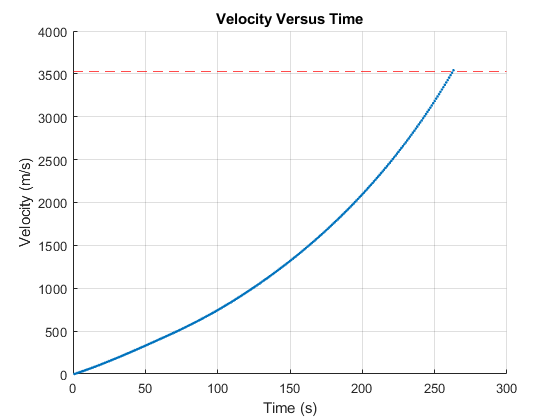


figure(2) % graphing velocity versus time
scatter(t,real(u),'.')
title('Velocity Versus Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
yline(3524.636832,'r--')
grid on

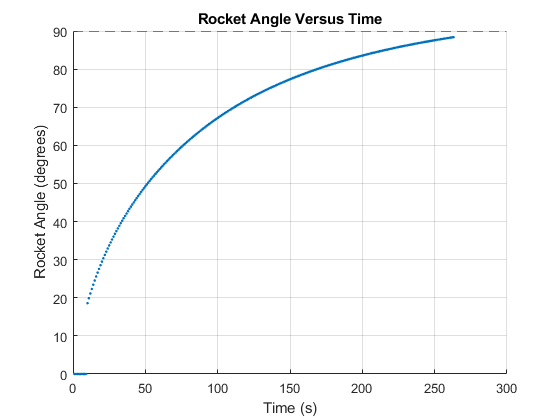


figure(3) % graphing angle in degrees versus time
scatter(t,real(theta*180/pi),'.')
title('Rocket Angle Versus Time')
xlabel('Time (s)')
ylabel('Rocket Angle (degrees)')
yline(90,'r--')
grid on

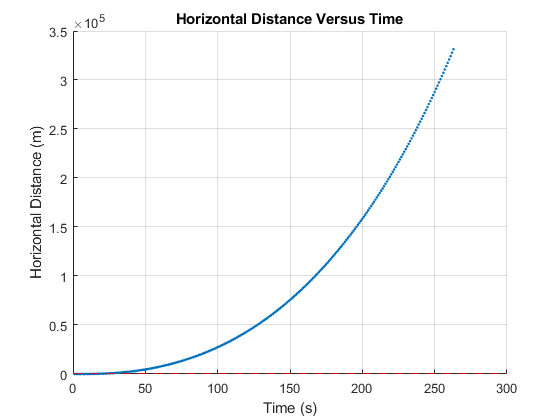


figure(4)
scatter(t,real(x),'.') % graphing horizontal position versus time
title('Horizontal Distance Versus Time')
xlabel('Time (s)')
ylabel('Horizontal Distance (m)')
yline(90,'r--')
grid on

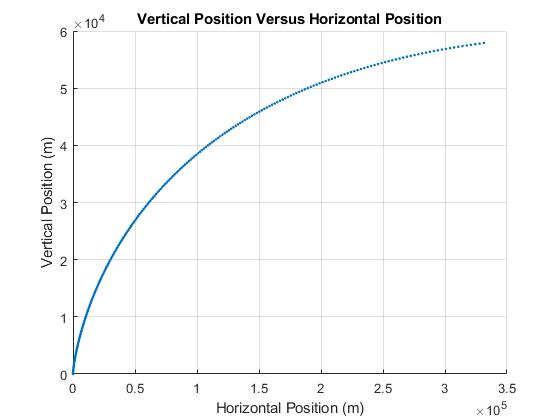

figure(5)
scatter(real(x),real(h),'.')
title('Vertical Position Versus Horizontal Position')
xlabel('Horizontal Position (m)')
ylabel('Vertical Position (m)')
grid on

disp(h(end)) % displaying final altitude

   5.7903e+04



disp(u(end)) % displaying final velocity

   3.5422e+03



disp(theta(end)*180/pi) % displaying final angle in degrees

   88.3797



disp(x(end)) % displaying final horizontal position

   3.3136e+05



### Task 2

mu_mars = 4.2828e4;     % gravitational parameter of Mars (km3/s2)
r0 = R_mars + h(end)    % initial orbital radius (m)

r0 = 3.4474e+06

g0 = g_mars_surf*(R_mars/r0)^2 % initial acceleration due to gravity (m/s2)

g0 = 3.5971

nu0 = 0.005; % initiial nu value
IC = [1;0;1;0]; % initial condition for ode45 @Tau = 0, [rho; (d/dTau)rho; (d2/dTau2)rho]


$$\begin{array}{l}
\frac{d}{d\tau }\left(\rho^2 \frac{d\theta }{d\tau }\right)=\nu \rho \\
\frac{d}{d\tau }{\left(\rho^3 \frac{d^2 \rho \;}{d\tau^2 }+\rho \;\right)}^{\frac{1}{2}} =\nu \rho \;
\end{array}$$


tspan_init = linspace(0,250,1000); % time variable for ode45 (s)
[Tau,S] = ode45(@eom,tspan_init,IC); % ode45 function for escape trajectory
rho = S(:,1);
drdTau= S(:,2);
B = S(:,3);
theta = S(:,4);

rdot = drdTau/r0/sqrt(r0 /g0); % change in radius over time (m/s)
r = rho*r0; % orbital radius for spacecraft (m)
thetadot = B./(rho.^2)/sqrt(r0/g0); % change in orbtial angle (rad/s)
v = sqrt(rdot.^2 + (r.*thetadot).^2);   % velocity of the spacecraft (m/s)
t_T2 = Tau*sqrt(r0/g0); % time past in escape trajectory (s)

Plot escape path using the code

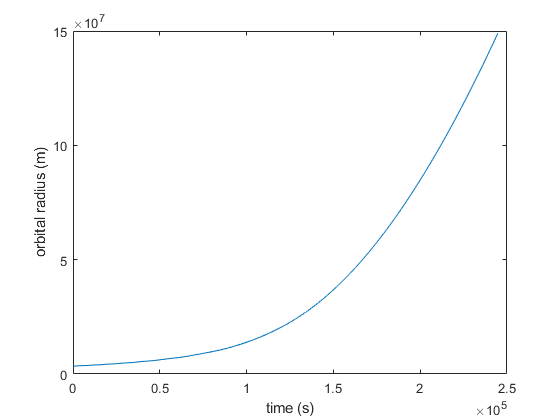

%just orbital radius for now
figure(6);
plot(t_T2,r) % plot of the orbital radius with respect to time
xlabel("time (s)")
ylabel("orbital radius (m)")

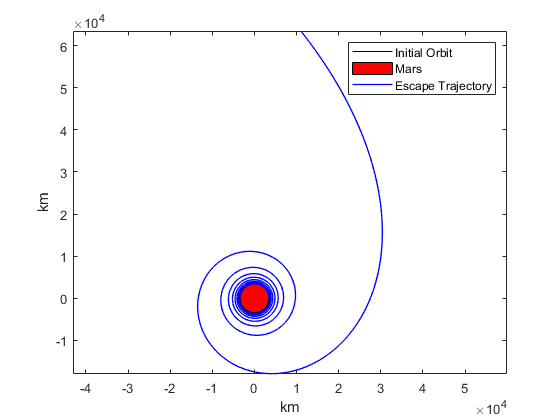

%initial orbit - circular
Ctheta = linspace(0,2*pi,200); % angle from 0:2*pi
x = r0*cos(Ctheta); 
y = r0*sin(Ctheta);
plot(x/1000,y/1000,"-k")

%Mars body
hold on
RX = R_mars*cos(Ctheta);
RY = R_mars*sin(Ctheta); 
fill(RX/1000,RY/1000,"r")

%To escape
vesc_t = sqrt(2*mu_mars./(r/1000))*1000;   %m/s
index = find(v>vesc_t); % index of the time step where the spacecraft velocity is greater than the escape velocity
limit = index(1); % the time the spacecraft reaches escape velocity
rx = r(1:limit).*cos(theta(1:limit)); % x compoenent of escape velocuty
ry = r(1:limit).*sin(theta(1:limit)); % y compoenent of escape velocity
plot(rx/1000,ry/1000,"b","LineWidth",1) 

%Post-Processing
xlabel("km")
ylabel("km")
legend("Initial Orbit","Mars","Escape Trajectory")
axis equal
hold off

Time required to escape + escape velocity

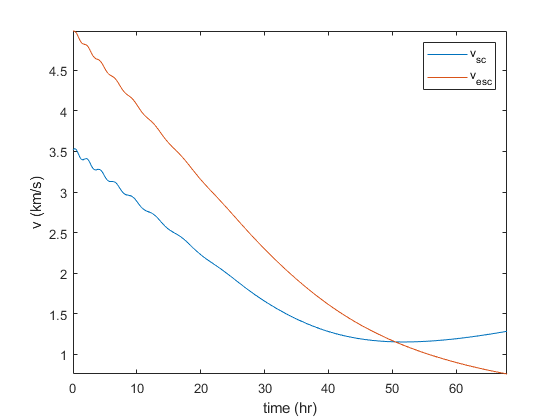

figure;
plot(t_T2/3600,v/1000) % spacecraft velocity
hold on 
plot(t_T2/3600,vesc_t/1000) % escape velocty 
legend("v_s_c","v_e_s_c")
xlabel("time (hr)")
ylabel("v (km/s)")
axis tight
hold off

Time unit conversion

tesc_sec = mod(t_T2(limit),60); % time to escape in seconds
tesc_hr = t_T2(limit)/3600;    % time to escape in hr
tesc_min = t_T2(limit)/60-floor(tesc_hr)*60; % time to escape in min
tesc = t_T2(limit) % time until escape velocity

tesc = 1.8178e+05

vesc = v(limit); % escape velocity (m/s)
fprintf("Spacecraft escapes Mars %.0f hours and %.0f minutes into the Low Thrust manuever (LTM) at %.2f m/s",tesc_hr,tesc_min,vesc)

Spacecraft escapes Mars 50 hours and 30 minutes into the Low Thrust manuever (LTM) at 1154.18 m/s

Velocity increment ($\Delta u$) comparison

du = .005*tesc/1000;% delta change in velocity
du_imp = (sqrt(2)-1)*sqrt(mu_mars/(r0/1000)); % impulsive change in velocity
fprintf("\nThe velocity increment for the LTM is %.4f km/s while the impulsive velocity increment is %.4f km/s",du,du_imp)


The velocity increment for the LTM is 0.9089 km/s while the impulsive velocity increment is 1.4600 km/s

fprintf("\nDelta_u < Delta_u_impulse")


Delta_u < Delta_u_impulse

First order ODEs:


$$\begin{array}{l}
\frac{d\rho }{d\tau }=A\\
\frac{\textrm{dA}}{d\tau }=\frac{B^2 -\rho }{\rho^3 }\\
\frac{\textrm{dB}}{d\tau }=\nu \rho \\
\frac{d\theta }{d\tau }=\frac{B}{\rho^2 }
\end{array}$$



$$s=\left\lbrack \rho ;A;B;\theta \right\rbrack$$


function dRdT= eom(~,s) 
    nu = 0.005; %nu is constant atm
    drho = s(2); 
    dA = (s(3)^2 - s(1))/(s(1)^3);
    dB = nu*s(1); 
    dtheta = s(3)/(s(1)^2);
    dRdT = [drho; dA; dB; dtheta]; 
end
